1


$$\begin{array}{l}
x~\Gamma \left(2,2\right)\\
\Gamma \left(\alpha ,\beta \right)=x^{\alpha -1} \frac{e^{-\frac{x}{\beta }} }{\beta^{\alpha } \Gamma \left(\alpha \right)}\\
\mu =\alpha \beta \\
\sigma =\beta \sqrt{\alpha }\\
\mu -\sigma =\alpha \beta -\beta \sqrt{\alpha }=4-2\sqrt{2}\\
\mu +\sigma =\alpha \beta +\beta \sqrt{\alpha }=4+2\sqrt{2}\\
C=\int_{\alpha \beta -\beta \sqrt{\alpha }}^{\alpha \beta +\beta \sqrt{\alpha }} x^{2-1} \frac{e^{-\frac{x}{2}} }{2^2 \Gamma \left(2\right)}\mathrm{dx}=\frac{1}{4\Gamma \left(2\right)}\int_{\alpha \beta -\beta \sqrt{\alpha }}^{\alpha \beta +\beta \sqrt{\alpha }} xe^{-\frac{x}{2}} \mathrm{dx}\\
I=\int xe^{-\frac{x}{2}} \mathrm{dx}\\
u=-\frac{x}{2}\\
\mathrm{du}=-\frac{1}{2}\mathrm{dx}\\
x=-2u\\
I=4\int ue^u \mathrm{dx}\\
=4\left(ue^u -e^u \right)\\
=4\left(-\frac{x}{2}e^{-\frac{x}{2}} -e^{-\frac{x}{2}} \right)\\
C={\left(-\frac{x}{2}e^{-\frac{x}{2}} -e^{-\frac{x}{2}} \right)}_{4-2\sqrt{2}}^{4+2\sqrt{2}} \\
=\left(-\frac{4+2\sqrt{2}}{2}e^{-\frac{\left(4+2\sqrt{2}\right)}{2}} -e^{-\frac{\left(4+2\sqrt{2}\right)}{2}} \right)-\left(-\frac{4-2\sqrt{2}}{2}e^{-\frac{\left(4-2\sqrt{2}\right)}{2}} -e^{-\frac{\left(4-2\sqrt{2}\right)}{2}} \right)\\
=-\frac{4+2\sqrt{2}}{2}e^{-\frac{\left(4+2\sqrt{2}\right)}{2}} -e^{-\frac{\left(4+2\sqrt{2}\right)}{2}} -\frac{4-2\sqrt{2}}{2}e^{-\frac{\left(4-2\sqrt{2}\right)}{2}} +e^{-\frac{\left(4-2\sqrt{2}\right)}{2}} \\
=-\left(2+\sqrt{2}\right)e^{-\left(2+\sqrt{2}\right)} -e^{-\left(2+\sqrt{2}\right)} -\left(2-\sqrt{2}\right)e^{-\left(2-\sqrt{2}\right)} +e^{-\left(2-\sqrt{2}\right)} \\
=-2e^{-\left(2+\sqrt{2}\right)} -\sqrt{2}e^{-\left(2+\sqrt{2}\right)} -e^{-\left(2+\sqrt{2}\right)} -2e^{-\left(2-\sqrt{2}\right)} +\sqrt{2}e^{-\left(2-\sqrt{2}\right)} +e^{-\left(2-\sqrt{2}\right)} \\
=-2e^{-2-\sqrt{2}} -\sqrt{2}e^{-2-\sqrt{2}} -e^{-2-\sqrt{2}} -2e^{-2+\sqrt{2}} +\sqrt{2}e^{-2+\sqrt{2}} +e^{-2+\sqrt{2}} \\
=0\ldotp 7375
\end{array}$$


2)

n = 100;
A = 0;
a = 2;
b = 2;
mu=a*b;
Sigma=b*sqrt(a);
bot = mu-Sigma;
up = mu+Sigma;
Dx = (up - bot)/n;
x_star = linspace(bot + Dx/2, up - Dx/2, n);
for i = 1 : n
   A = A + f(x_star(i),a,b)*Dx;
end
A

A = 0.7375

result of integral is 0.7375

3)


$$\begin{array}{l}
x~\Gamma \left(2,2\right)\\
\Gamma \left(\alpha ,\beta \right)=x^{\alpha -1} \frac{e^{-\frac{x}{\beta }} }{\beta^{\alpha } \Gamma \left(\alpha \right)}\\
\mu =\alpha \beta =4\\
\sigma =\beta \sqrt{\alpha }=2\sqrt{2}=2\ldotp 8284
\end{array}$$


4)

n_4 = 100;
A_4 = 0;
a_4=2;
b_4=2;
bot_4 = 0;
up_4 = 100;
Dx_4 = (up_4 - bot_4)/n_4;
x_star_4 = linspace(bot_4 + Dx_4/2, up_4 - Dx_4/2, n_4);
for i = 1 : n_4
   A_4 = A_4 + fx(x_star_4(i), a_4, b_4)*Dx_4;
end
A_4

A_4 = 4.0009

the result is 4.0009

which is similar with 3)

5)


$${\left(\frac{\partial }{\partial x}f\left(x\right)\right)}_{\hat{x} } =0$$



$$\begin{array}{l}
\frac{\partial }{\partial x}\left(x^{\alpha -1} \frac{e^{-\frac{x}{\beta }} }{\beta^{\alpha } \Gamma \left(\alpha \right)}\right)=0\\
{\left(\alpha -1\right)x}^{\alpha -2} e^{-\frac{x}{\beta }} +x^{\alpha -1} {\left(-\frac{1}{\beta }\right)e}^{-\frac{x}{\beta }} =0\\
{\left(\alpha -1\right)x}^{\alpha -2} -\frac{1}{\beta }x^{\alpha -1} =0\\
{\left(\alpha -1\right)x}^{\alpha -2} -\frac{x}{\beta }x^{\alpha -1-1} =0\\
{\left(\alpha -1\right)x}^{\alpha -2} -\frac{x}{\beta }x^{\alpha -2} =0\\
\left(\alpha -1-\frac{x}{\beta }\right)x^{\alpha -2} =0\\
\left(\alpha -1-\frac{x}{\beta }\right)=0\\
\hat{x} =\beta \left(\alpha -1\right)
\end{array}$$


6)

a_6 = 2;
b_6 = 2;
bot_6 = 0;
up_6 = 100;
dx_6=0.001;
x_star_6 = bot_6:dx_6:up_6;
L=length(x_star_6);
df=zeros(1,L-1);
for i=1:L-1
    df(i)=(f(x_star_6(i+1),a_6,b_6)-f(x_star_6(i),a_6,b_6))/dx_6;
end

Ldf=length(df);
for i=1:Ldf
    if df(i)>=-dx_6 && df(i)<=dx_6
        x_hat=x_star_6(i);
        break
    end
end
x_hat

x_hat = 1.9780

the result is 1.9780

which is similar with:


$$\beta \left(\alpha -1\right)=2$$


7)

a_7 = 2;
b_7 = 2;

x_0=0;
p50=0.5

p50 = 0.5000

p99=0.99

p99 = 0.9900


while x_0>=0    
    if Gcdf(a_7,b_7,0,x_0)>p50
        x50=x_0;
        break
    end
    x_0=x_0+0.001;
end



x_0=0;
while x_0>=0    
    if Gcdf(a_7,b_7,0,x_0)>p99
        x99=x_0;
        break
    end
    x_0=x_0+0.001;
end

x50

x50 = 3.3570

x99

x99 = 13.2350

50th percentile is 3.3570

99th percentile is 13.2350

50th percentile is less than the mean 

50th percentile is larger than the mode 

8)

num=10e6;
x_8 = gamrnd(a_7,b_7,num,1);
sort_x_8 = sort(x_8);
x_50_n = sort_x_8(p50*num)

x_50_n = 3.3567

x_99_n = sort_x_8(p99*num)

x_99_n = 13.2874

50th percentile and 99th percentile is close to 7)


$$\mathrm{median}=\alpha \beta \frac{3\alpha -0\ldotp 8}{3\alpha +0\ldotp 2}=4\left(\frac{6-0\ldotp 8}{6+0\ldotp 2}\right)=4\left(\frac{5\ldotp 2}{6\ldotp 2}\right)=3\ldotp 3548$$


which 50th percentile in 7) is close to the approximate median

9)

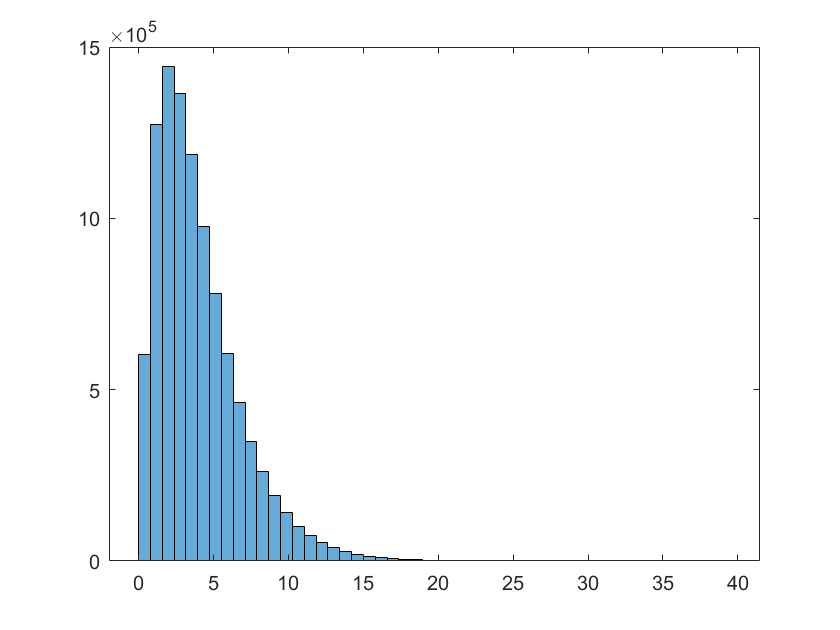

H =   Histogram - 属性:

             Data: [10000000×1 double]
           Values: [1×50 double]
          NumBins: 50
         BinEdges: [1×51 double]
         BinWidth: 0.7900
        BinLimits: [0 39.5000]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  显示 所有属性


H=histogram(x_8,'NumBins',50)

RNP=H.Values/num;
RNX=H.BinEdges(1:H.NumBins);
x_9=RNX

x_9 =          0    0.7900    1.5800    2.3700    3.1600    3.9500    4.7400    5.5300    6.3200    7.1100    7.9000    8.6900    9.4800   10.2700   11.0600   11.8500   12.6400   13.4300   14.2200   15.0100   15.8000   16.5900   17.3800   18.1700   18.9600   19.7500   20.5400   21.3300   22.1200   22.9100   23.7000   24.4900   25.2800   26.0700   26.8600   27.6500   28.4400   29.2300   30.0200   30.8100   31.6000   32.3900   33.1800   33.9700   34.7600   35.5500   36.3400   37.1300   37.9200   38.7100



Gpdf_9=gampdf(x_9,a_7,b_7)

Gpdf_9 =          0    0.1331    0.1793    0.1812    0.1627    0.1370    0.1108    0.0871    0.0670    0.0508    0.0380    0.0282    0.0207    0.0151    0.0110    0.0079    0.0057    0.0041    0.0029    0.0021    0.0015    0.0010    0.0007    0.0005    0.0004    0.0003    0.0002    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


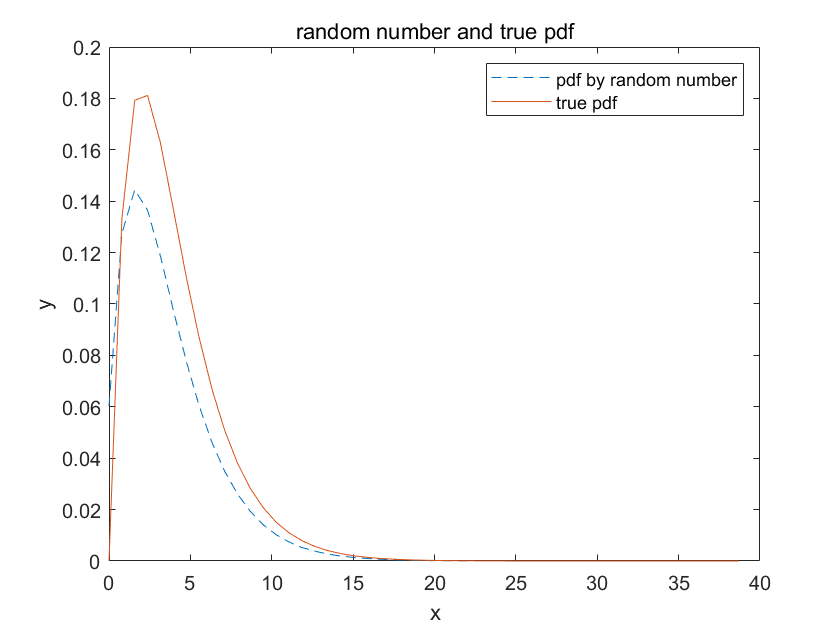


plot(RNX,RNP,'--')
hold on
plot(x_9,Gpdf_9,'-')
legend('pdf by random number','true pdf')
xlabel('x')
ylabel('y')
title('random number and true pdf')
hold off

10)

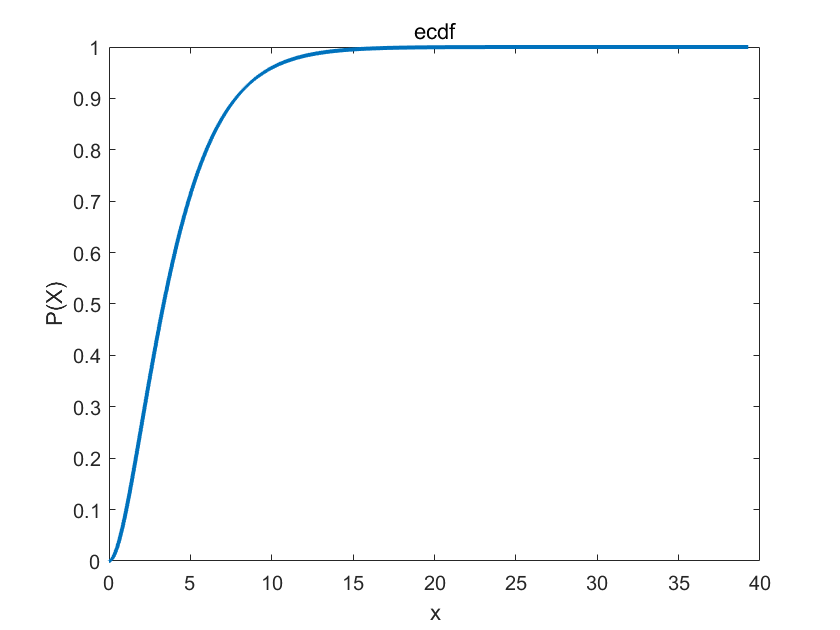

[F,x_ecdf]=ecdf(x_8);

stairs(x_ecdf,F,'LineWidth',2)
xlabel('x')
ylabel('P(X)')
title('ecdf')

11)


$$f\left(x\right)=\lambda e^{-\lambda x}$$


Mean


$$\mu =\int_0^{\infty } x\lambda e^{-\lambda x} \mathrm{dx}=\lambda \int_0^{\infty } xe^{-\lambda x} \mathrm{dx}$$


Which can be seen as $\Gamma \left(\alpha ,\beta \right)$ with$\alpha =2,\beta =\frac{1}{\lambda }$


$$\begin{array}{l}
\int_0^{\infty } \Gamma \left(2,\frac{1}{\lambda }\right)\mathrm{dx}=1\\
\int_0^{\infty } x^{2-1} \frac{e^{-\frac{x}{\frac{1}{\lambda }}} }{{\left(\frac{1}{\lambda }\right)}^2 \Gamma \left(2\right)}\mathrm{dx}=1\\
\int_0^{\infty } x\frac{e^{-\lambda x} }{\frac{1}{\lambda^2 }}\mathrm{dx}=1\\
\int_0^{\infty } xe^{-\lambda x} \mathrm{dx}=\frac{1}{\lambda^2 }\\
\lambda \int_0^{\infty } xe^{-\lambda x} \mathrm{dx}=\frac{\lambda }{\lambda^2 }=\frac{1}{\lambda }
\end{array}$$


Median


$$\begin{array}{l}
\int_0^{\widetilde{x} } \lambda e^{-\lambda x} \mathrm{dx}=\frac{1}{2}\\
{\left({-e}^{-\lambda x} \right)}_0^{\widetilde{x} } =\frac{1}{2}\\
{-e}^{-\lambda \widetilde{x} } +1=\frac{1}{2}\\
e^{-\lambda \widetilde{x} } =\frac{1}{2}\\
-\lambda \widetilde{x} =\mathrm{ln}\left(\frac{1}{2}\right)\\
\lambda \widetilde{x} =\mathrm{ln}\left(2\right)\\
\widetilde{x} =\frac{\mathrm{ln}\left(2\right)}{\lambda }
\end{array}$$


variance


$$\begin{array}{l}
\sigma^2 =\int_0^{\infty } {\left(x-\mu \right)}^2 \lambda e^{-\lambda x} \mathrm{dx}\\
=\int_0^{\infty } {\left(x-\frac{1}{\lambda }\right)}^2 \lambda e^{-\lambda x} \mathrm{dx}\\
=\int_0^{\infty } \left(x^2 -2\frac{x}{\lambda }+\frac{1}{\lambda^2 }\right)\lambda e^{-\lambda x} \mathrm{dx}\\
=\int_0^{\infty } \left(x^2 \lambda e^{-\lambda x} -2xe^{-\lambda x} +\frac{1}{\lambda }e^{-\lambda x} \right)\mathrm{dx}\\
=\lambda \int_0^{\infty } \left(x^2 e^{-\lambda x} \right)\mathrm{dx}-2\int_0^{\infty } \left(xe^{-\lambda x} \right)\mathrm{dx}+\frac{1}{\lambda }\int_0^{\infty } \left(e^{-\lambda x} \right)\mathrm{dx}\\
=2\lambda {\left(\frac{1}{\lambda }\right)}^3 -\frac{2}{\lambda^2 }+\frac{1}{\lambda^2 }=\frac{1}{\lambda^2 }
\end{array}$$
    

12)

Chi-square


$${f\left(x\right)=x}^{\frac{\nu }{2}-1} \frac{e^{-\frac{x}{2}} }{2^{\frac{\nu }{2}} \Gamma \left(\frac{\nu }{2}\right)}$$


which is same as$\;\Gamma \left(\alpha ,\beta \right)$ with$\alpha =\frac{\nu }{2},\beta =2$

so


$$\begin{array}{l}
\mu =\alpha \beta =\nu \\
\sigma^2 =\alpha \beta^2 =2\nu 
\end{array}$$


median of chi is


$$\begin{array}{l}
\int_0^m x^{\frac{\nu }{2}-1} \frac{e^{-\frac{x}{2}} }{2^{\frac{\nu }{2}} \Gamma \left(\frac{\nu }{2}\right)}\mathrm{dx}=\frac{1}{2}\\
2^{\frac{\nu }{2}} \Gamma \left(\frac{\nu }{2}\right)\int_0^m x^{\frac{\nu }{2}-1} e^{-\frac{x}{2}} \mathrm{dx}=\frac{1}{2}\\
\frac{\Gamma \left(\frac{\nu }{2},\frac{m}{2}\right)}{\Gamma \left(\frac{\nu }{2}\right)}=\frac{1}{2}\\
\Gamma \left(\frac{\nu }{2},\frac{m}{2}\right)=\frac{1}{2}\Gamma \left(\frac{\nu }{2}\right)
\end{array}$$


solve for m

function [y] = f(x,a,b)
    y = x^(a-1)*exp(-x/b)/(b^a*gamma(a));
end

function [y] = fx(x,a,b)
    y = x*x^(a-1)*exp(-x/b)/(b^a*gamma(a));
end

function [A]=Gcdf(a,b,bot,up)
    n = 100;
    A = 0;
    Dx = (up - bot)/n;
    x_star = linspace(bot + Dx/2, up - Dx/2, n);
    for i = 1 : n
        A = A + f(x_star(i),a,b)*Dx;
    end
end